# LCE-05 精密整流

## 输出信号 FFT (input 50 Hz)

data = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\1N5711 input-output waveform (50 Hz) several circles.txt");
%data = readmatrix("D:\a_RemoteRepo\GH.UCAS-LinearCircuitExpe\LCE-05-精密整流\data\1N4148 input-output waveform (50 Hz).txt");
stc = MyAnalysis_Spectrum_3fig_amp(data(:, 3)', data(:, 1)' - data(1, 1));

采样频率：16000 Hz
频谱分辨率: 1.9531 Hz
Time range: 0 to 0.51194


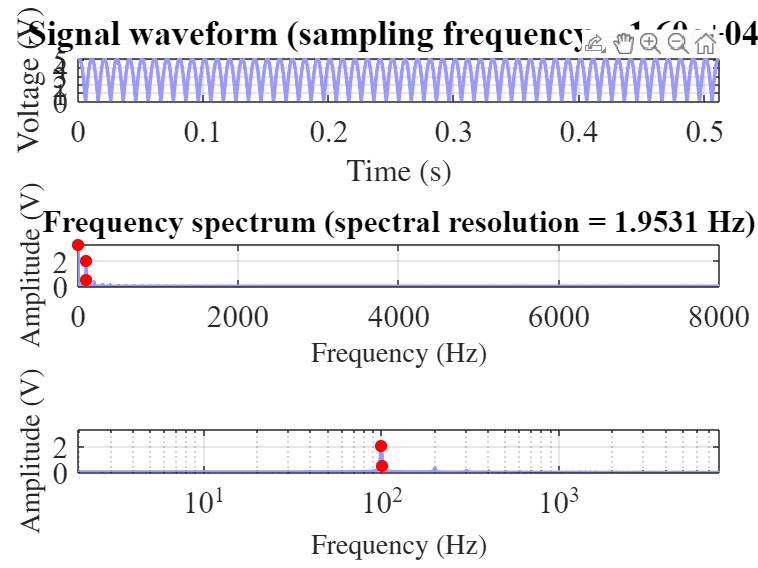

stc = 包含以下字段的 struct :
             f: [0 1.9531 3.9063 5.8594 7.8125 9.7656 11.7188 13.6719 15.6250 17.5781 19.5313 21.4844 23.4375 25.3906 27.3438 29.2969 31.2500 33.2031 35.1563 37.1094 39.0625 41.0156 42.9688 44.9219 46.8750 48.8281 50.7813 52.7344 54.6875 56.6406 … ]
             L: 8192
            Fs: 1.6000e+04
            Ts: 6.2500e-05
            P1: [3.2751 0.0139 0.0141 0.0139 0.0141 0.0140 0.0140 0.0141 0.0142 0.0143 0.0144 0.0147 0.0148 0.0149 0.0151 0.0154 0.0155 0.0158 0.0160 0.0164 0.0166 0.0170 0.0174 0.0178 0.0183 0.0197 0.0217 0.0200 0.0205 0.0212 0.0220 0.0229 0.0238 … ]
         P1_dB: [0 -47.4149 -47.3181 -47.4470 -47.3107 -47.3754 -47.3891 -47.2975 -47.2652 -47.2237 -47.1347 -46.9855 -46.8857 -46.8141 -46.7482 -46.5788 -46.4882 -46.3291 -46.2271 -46.0294 -45.9187 -45.6870 -45.4929 -45.3160 -45.0670 -44.4141 … ]
            P2: [3.2751 0.0070 0.0071 0.0069 0.0071 0.0070 0.0070 0.0071 0.0071 0.0071 0.0072 0.0073 0.0074 0.0075 0.0075 0.0077 0.0078 0.0079 0.0080 0.

stc.ax0.YLim(1) = 0;
stc.ax0.YTick = 0:1:5

## 输入信号幅度与输出信号平均值

data = [
5.0	3.2680
4.5	2.9419
4.0	2.6175
3.7	2.4219
3.4	2.2269
3.1	2.0314
2.8	1.8358
2.5	1.6408
2.2	1.4454
1.9	1.2505
1.6	1.0425
1.3	0.8472
1.0	0.6526    
];
[fitresult, stc, gof] = MyFit_proportional(data(:, 1)', data(:, 2)', 1);

y = ax
a = 6.5454e-01
R^2  = 0.9999726
SSE  = 2.18038e-04
RMSE = 4.26261e-03


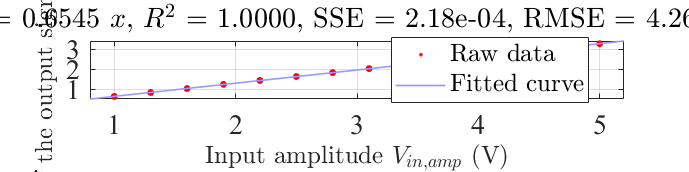

stc.label.x.String = 'Input amplitude $V_{in,amp}$ (V)';
stc.label.y.String = 'Mean value of the output signal $(V_{out})_{mean}$ (V)';
MyFigure_ChangeSize_2048x512
MyExport_pdf

V1 = 3.2674 % 50 Hz, input 5Vamp 的输出平均值

V1 = 3.2674

V1*0.99

ans = 3.2347



V1 = 3.2679 % 50 Hz, input 5Vamp 的输出平均值

V1 = 3.2679

V1*0.99

ans = 3.2352

omega = 2*pi*50;
T = 1/50;
syms t
Vin = 5*sin(omega*t)
mean = 1/T*int(abs(Vin), t, 0, T)
vpa(mean)

V1 = [2.5942, 2.0381, 0.2733]
RMS = [2.8504, 2.3273, 0.9004]
[V1; RMS]/4*5